% Script pour exécuter l'analyse des EMG avec SPM1D, DTW et sélection de cycles
fprintf('Analyse des profils EMG moyens par muscle avec SPM1D et DTW\n');

Analyse des profils EMG moyens par muscle avec SPM1D et DTW


fprintf('======================================================\n\n');


% Ajouter le chemin vers la bibliothèque SPM1D
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Statistics\spm1dmatlab-master'))

% Demander si on souhaite utiliser l'alignement DTW
fprintf('Souhaitez-vous utiliser l''alignement DTW pour les courbes? (O/N): ');

Souhaitez-vous utiliser l'alignement DTW pour les courbes? (O/N): 

use_dtw_input = input('', 's');
use_dtw = lower(use_dtw_input) == 'o' || lower(use_dtw_input) == 'y' || isempty(use_dtw_input);
if use_dtw
    fprintf('Alignement DTW activé.\n');
else
    fprintf('Alignement DTW désactivé.\n');
end

Alignement DTW activé.



% Demander le nombre de fichiers à analyser
fprintf('\nCombien de fichiers souhaitez-vous analyser? (1-3): ');


Combien de fichiers souhaitez-vous analyser? (1-3): 

num_files = str2double(input('', 's'));

% Vérifier la validité du nombre
if isnan(num_files) || num_files < 1 || num_files > 3
    fprintf('Nombre invalide. Utilisation d''un seul fichier par défaut.\n');
    num_files = 1;
end

% Collecter les noms de fichiers
data_files = cell(num_files, 1);
for i = 1:num_files
    default_file = sprintf('combined_functional_data_for_spm1d_%d.mat', i);
    if i == 1
        default_file = 'combined_functional_data_for_spm1d.mat';
    end
    fprintf('\nFichier #%d:\n', i);
    fprintf('Quel fichier de données voulez-vous utiliser? (défaut: %s)\n', default_file);
    file_name = input('Nom du fichier (appuyez sur Entrée pour utiliser la valeur par défaut): ', 's');
    if isempty(file_name)
        file_name = default_file;
    end
    % Ajouter l'extension .mat si nécessaire
    if ~contains(file_name, '.mat')
        file_name = [file_name '.mat'];
    end
    data_files{i} = file_name;
end


Fichier #1:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d.mat)



Fichier #2:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d_2.mat)



Fichier #3:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d_3.mat)



======== SÉLECTION DE CYCLES ========
Souhaitez-vous sélectionner et moyenner trois cycles pour l'analyse? (O/N): 
Vous allez sélectionner 3 cycles qui seront moyennés pour l'analyse SPM.
Pour chaque muscle, vous devrez cliquer sur le début et la fin de chaque cycle (6 clics au total).
Les cycles seront ensuite moyennés pour l'analyse statistique.

Chargement des données depuis combined_functional_data_for_spm1d_asympt.mat...
Chargement des données depuis combined_functional_data_for_spm1d_preOP.mat...
Chargement des données depuis combined_functional_data_for_spm1d_postOP.mat...

======== SÉLECTION DES CYCLES - MUSCLE: RDELTA / LDELTA ========
Veuillez sélectionner 3 cycles pour le muscle RDELTA / LDELTA.
Pour chaque cycle, cliquez sur le graphique pour marquer:
  - Le début du cycle (premier clic)
  - La fin du cycle (deuxième clic)

Sélection du CYCLE 1/3:
Cliquez pour marquer le DÉBUT du cycle 1...
Début du cycle 1: 0.02%
Cliquez pour marquer la FIN du cycle 1...
Fin du cycle 1: 0

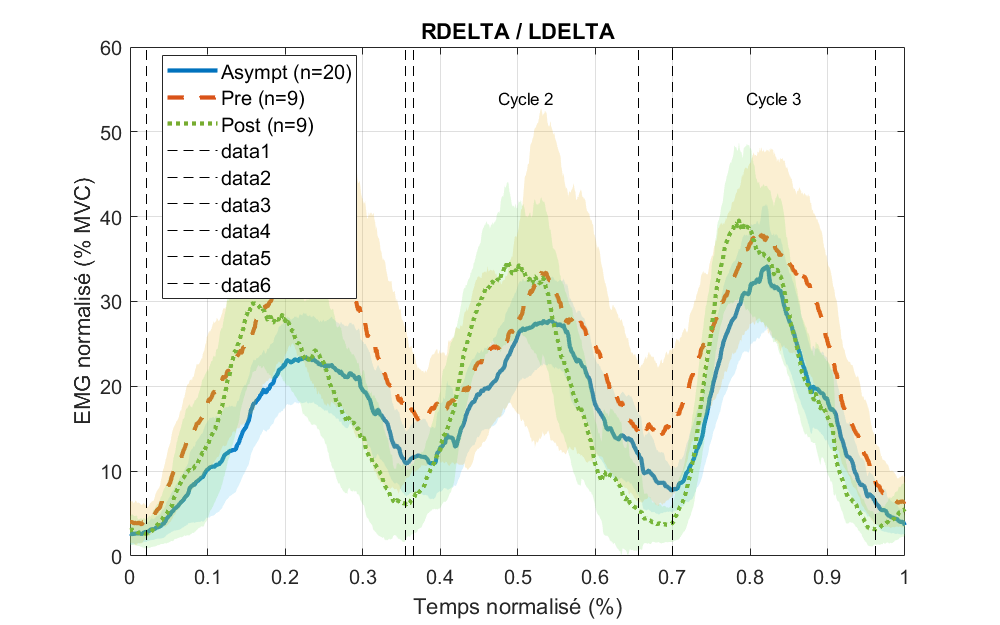


Tous les cycles ont été sélectionnés.
Création de la figure avec les cycles moyennés...



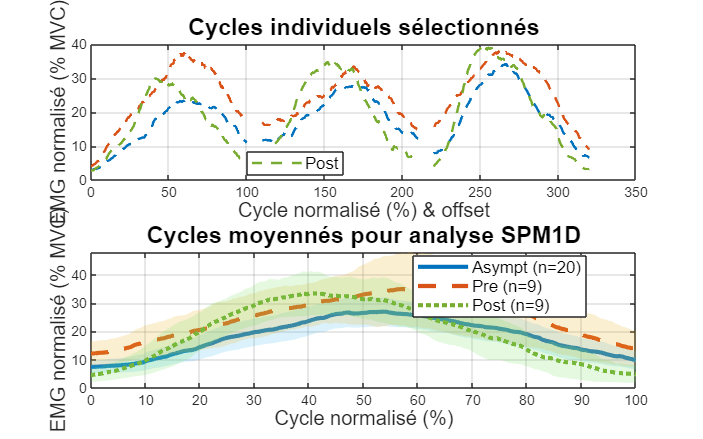

Alignement des courbes par DTW pour Asympt vs Pre...
Réalisation de l'analyse SPM1D pour Asympt vs Pre...
Type de test: Test t pour échantillons indépendants.


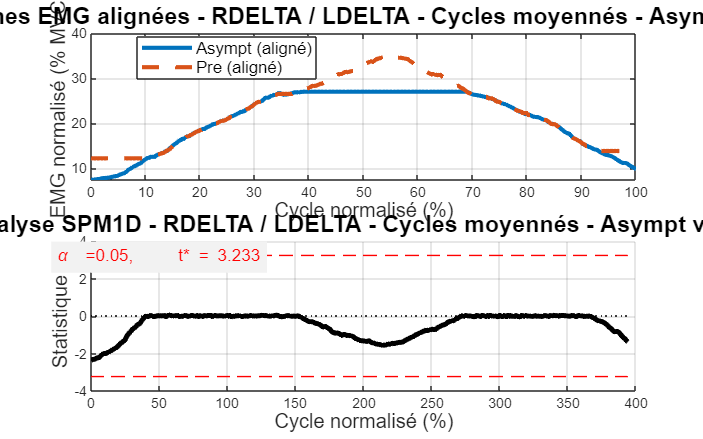

Alignement des courbes par DTW pour Asympt vs Post...
Réalisation de l'analyse SPM1D pour Asympt vs Post...
Type de test: Test t pour échantillons indépendants.


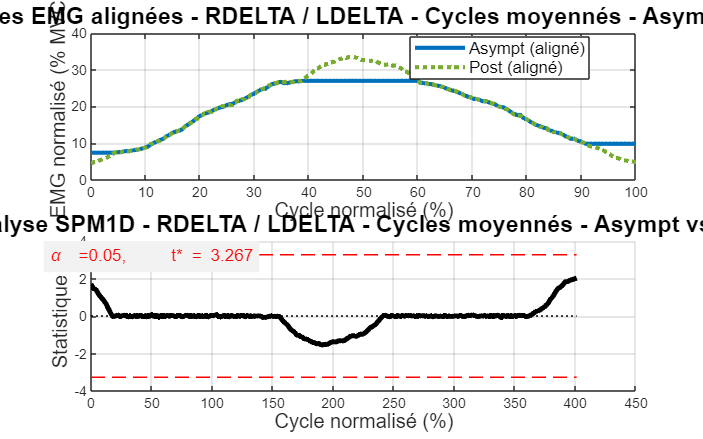

Alignement des courbes par DTW pour Pre vs Post...
Réalisation de l'analyse SPM1D pour Pre vs Post...
Type de test: Test t apparié (pour Pre vs Post).


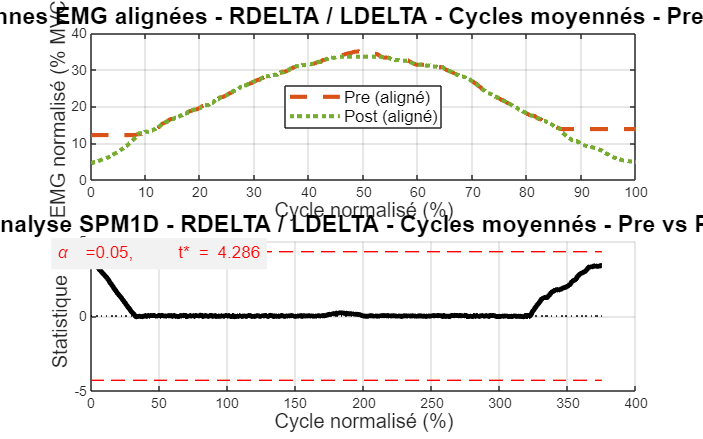


======== SÉLECTION DES CYCLES - MUSCLE: RDELTM / LDELTM ========
Veuillez sélectionner 3 cycles pour le muscle RDELTM / LDELTM.
Pour chaque cycle, cliquez sur le graphique pour marquer:
  - Le début du cycle (premier clic)
  - La fin du cycle (deuxième clic)

Sélection du CYCLE 1/3:
Cliquez pour marquer le DÉBUT du cycle 1...
Début du cycle 1: 0.03%
Cliquez pour marquer la FIN du cycle 1...
Fin du cycle 1: 0.39%
Sélection du CYCLE 2/3:
Cliquez pour marquer le DÉBUT du cycle 2...
Début du cycle 2: 0.40%
Cliquez pour marquer la FIN du cycle 2...
Fin du cycle 2: 0.67%
Sélection du CYCLE 3/3:
Cliquez pour marquer le DÉBUT du cycle 3...
Début du cycle 3: 0.70%
Cliquez pour marquer la FIN du cycle 3...
Fin du cycle 3: 0.96%

Tous les cycles ont été sélectionnés.
Création de la figure avec les cycles moyennés...



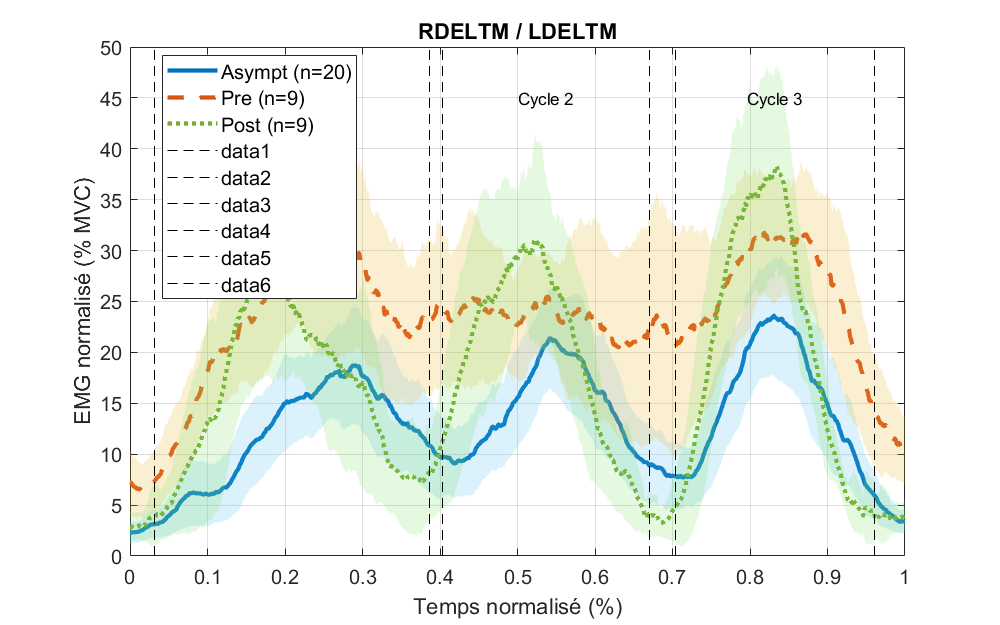

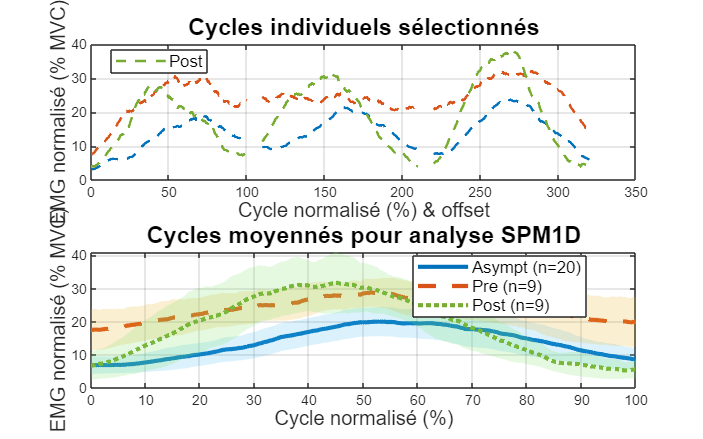

Alignement des courbes par DTW pour Asympt vs Pre...
Réalisation de l'analyse SPM1D pour Asympt vs Pre...
Type de test: Test t pour échantillons indépendants.


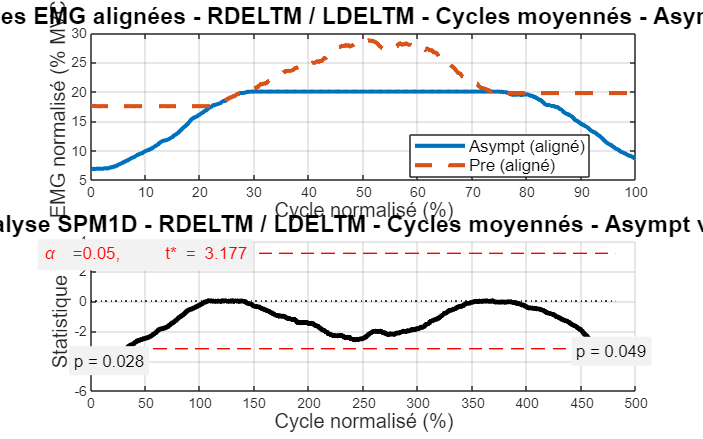

Alignement des courbes par DTW pour Asympt vs Post...
Réalisation de l'analyse SPM1D pour Asympt vs Post...
Type de test: Test t pour échantillons indépendants.


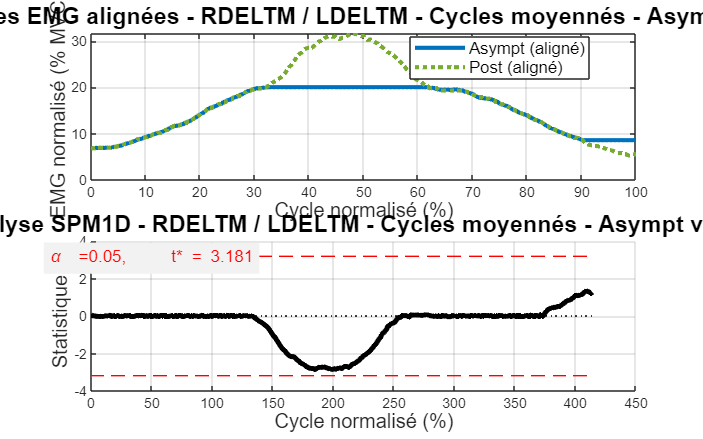

Alignement des courbes par DTW pour Pre vs Post...
Réalisation de l'analyse SPM1D pour Pre vs Post...
Type de test: Test t apparié (pour Pre vs Post).


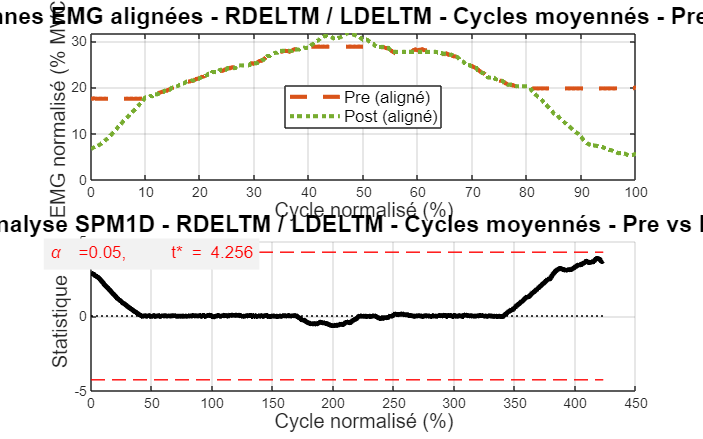


======== SÉLECTION DES CYCLES - MUSCLE: RDELTP / LDELTP ========
Veuillez sélectionner 3 cycles pour le muscle RDELTP / LDELTP.
Pour chaque cycle, cliquez sur le graphique pour marquer:
  - Le début du cycle (premier clic)
  - La fin du cycle (deuxième clic)

Sélection du CYCLE 1/3:
Cliquez pour marquer le DÉBUT du cycle 1...
Début du cycle 1: 0.02%
Cliquez pour marquer la FIN du cycle 1...
Fin du cycle 1: 0.40%
Sélection du CYCLE 2/3:
Cliquez pour marquer le DÉBUT du cycle 2...
Début du cycle 2: 0.41%
Cliquez pour marquer la FIN du cycle 2...
Fin du cycle 2: 0.69%
Sélection du CYCLE 3/3:
Cliquez pour marquer le DÉBUT du cycle 3...
Début du cycle 3: 0.72%
Cliquez pour marquer la FIN du cycle 3...
Fin du cycle 3: 0.97%

Tous les cycles ont été sélectionnés.
Création de la figure avec les cycles moyennés...



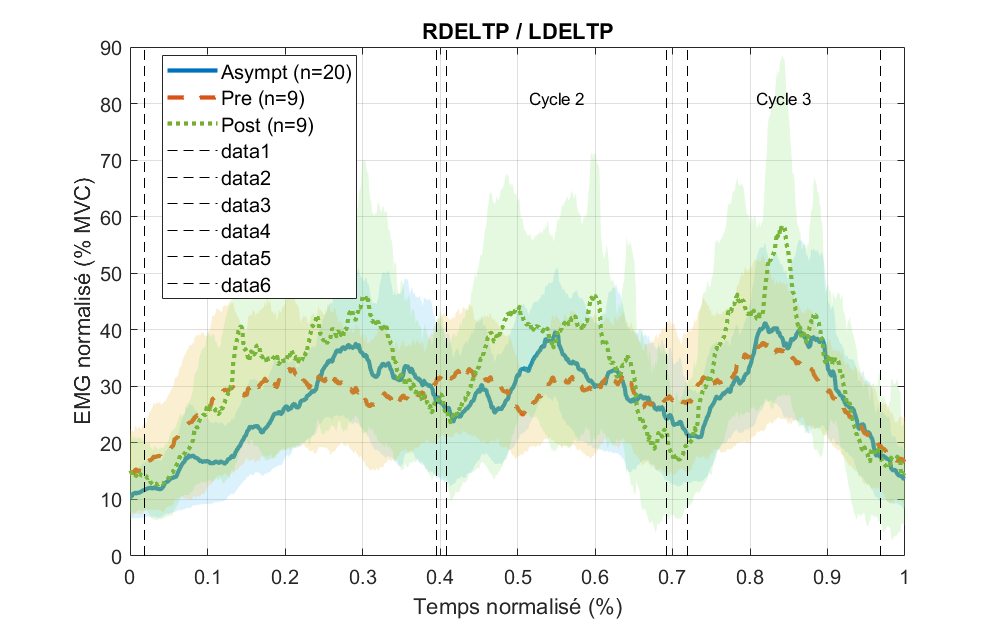

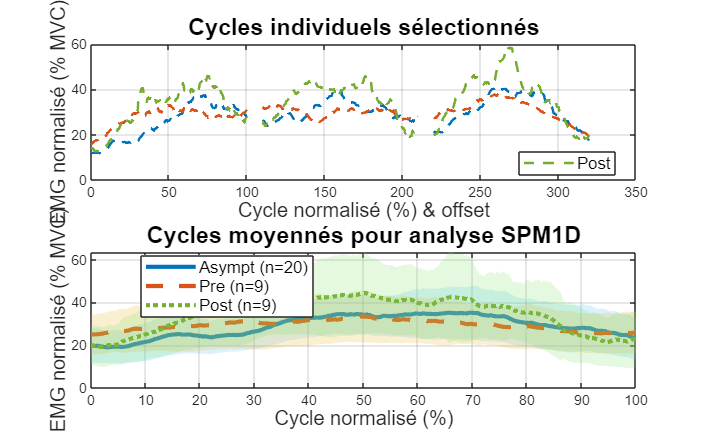

Alignement des courbes par DTW pour Asympt vs Pre...
Réalisation de l'analyse SPM1D pour Asympt vs Pre...
Type de test: Test t pour échantillons indépendants.


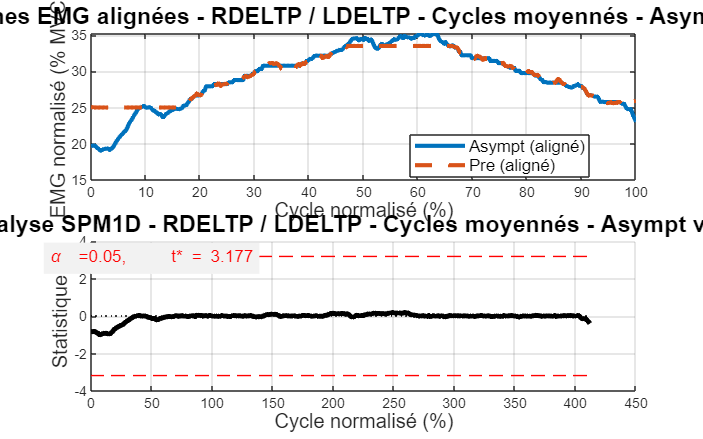

Alignement des courbes par DTW pour Asympt vs Post...
Réalisation de l'analyse SPM1D pour Asympt vs Post...
Type de test: Test t pour échantillons indépendants.


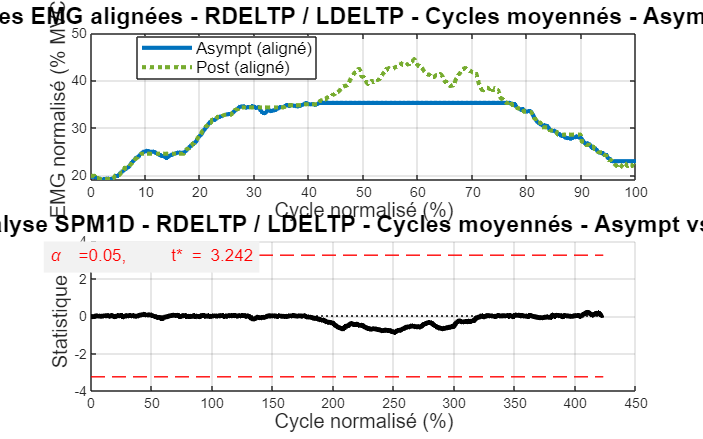

Alignement des courbes par DTW pour Pre vs Post...
Réalisation de l'analyse SPM1D pour Pre vs Post...
Type de test: Test t apparié (pour Pre vs Post).


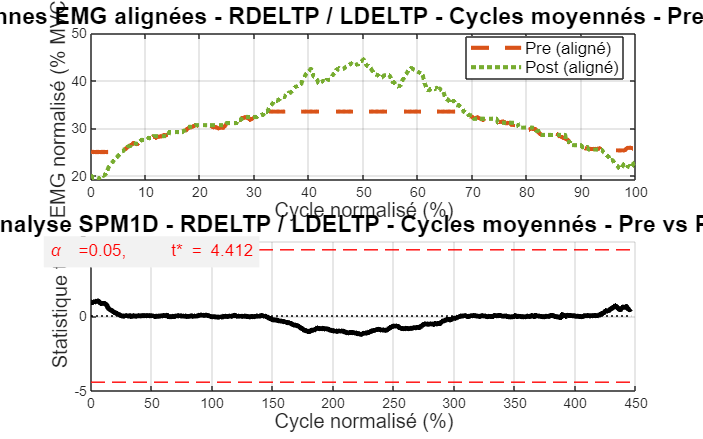


======== SÉLECTION DES CYCLES - MUSCLE: RTRAPM / LTRAPM ========
Veuillez sélectionner 3 cycles pour le muscle RTRAPM / LTRAPM.
Pour chaque cycle, cliquez sur le graphique pour marquer:
  - Le début du cycle (premier clic)
  - La fin du cycle (deuxième clic)

Sélection du CYCLE 1/3:
Cliquez pour marquer le DÉBUT du cycle 1...
Début du cycle 1: 0.02%
Cliquez pour marquer la FIN du cycle 1...
Fin du cycle 1: 0.37%
Sélection du CYCLE 2/3:
Cliquez pour marquer le DÉBUT du cycle 2...
Début du cycle 2: 0.39%
Cliquez pour marquer la FIN du cycle 2...
Fin du cycle 2: 0.69%
Sélection du CYCLE 3/3:
Cliquez pour marquer le DÉBUT du cycle 3...
Début du cycle 3: 0.70%
Cliquez pour marquer la FIN du cycle 3...
Fin du cycle 3: 0.95%

Tous les cycles ont été sélectionnés.
Création de la figure avec les cycles moyennés...



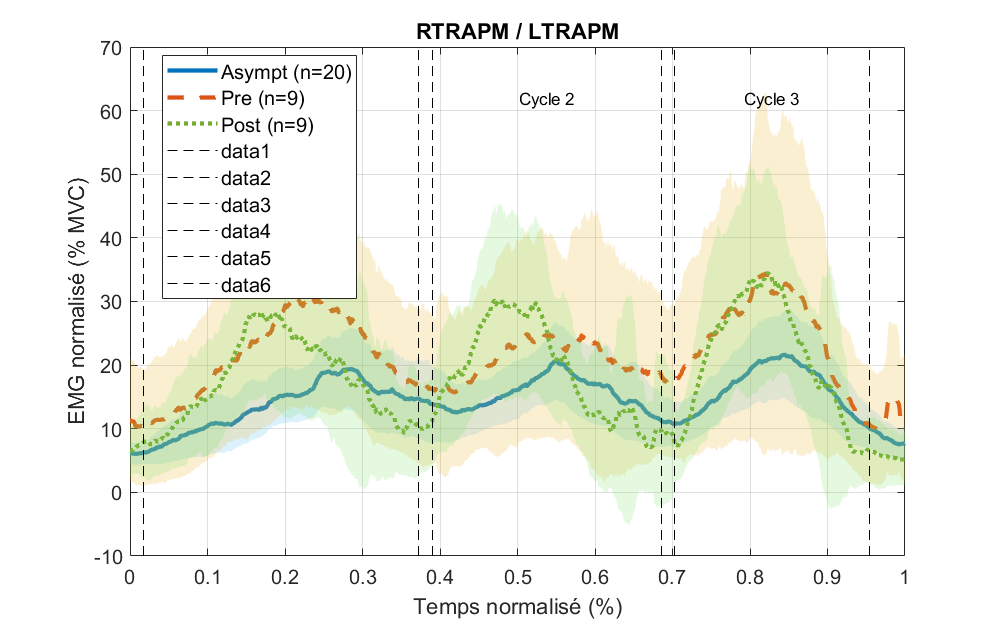

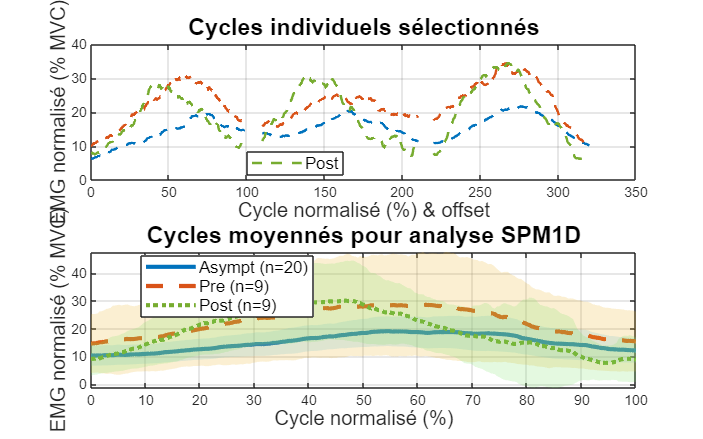

Alignement des courbes par DTW pour Asympt vs Pre...
Réalisation de l'analyse SPM1D pour Asympt vs Pre...
Type de test: Test t pour échantillons indépendants.


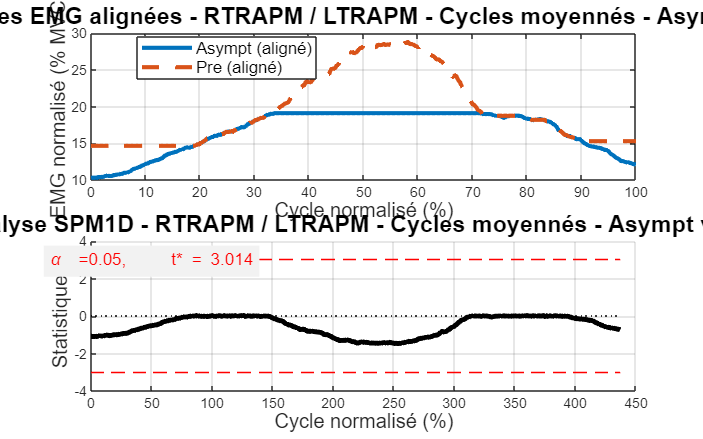

Alignement des courbes par DTW pour Asympt vs Post...
Réalisation de l'analyse SPM1D pour Asympt vs Post...
Type de test: Test t pour échantillons indépendants.


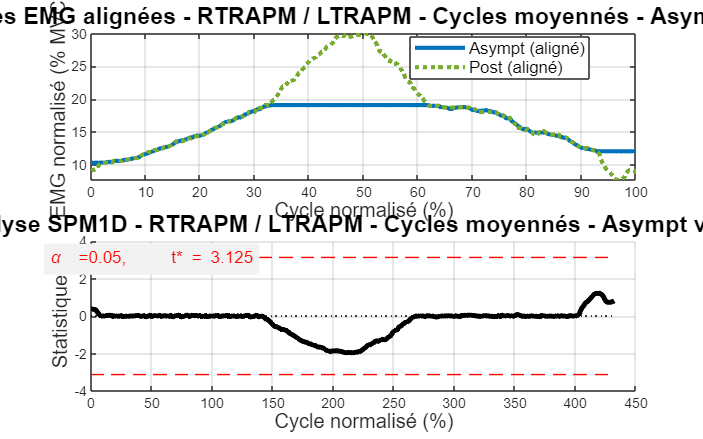

Alignement des courbes par DTW pour Pre vs Post...
Réalisation de l'analyse SPM1D pour Pre vs Post...
Type de test: Test t apparié (pour Pre vs Post).


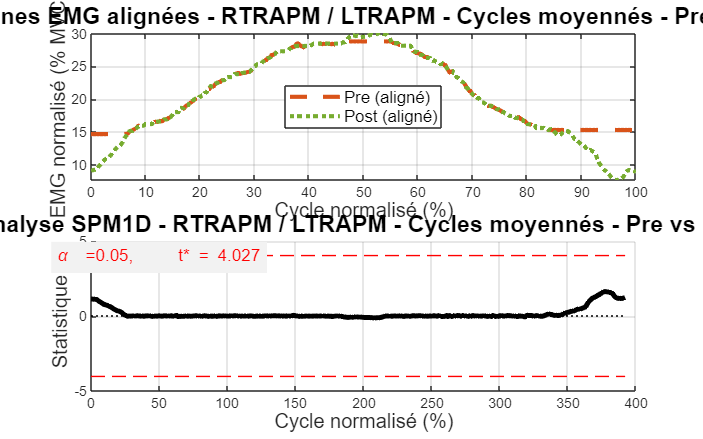


======== SÉLECTION DES CYCLES - MUSCLE: RTRAPS / LTRAPS ========
Veuillez sélectionner 3 cycles pour le muscle RTRAPS / LTRAPS.
Pour chaque cycle, cliquez sur le graphique pour marquer:
  - Le début du cycle (premier clic)
  - La fin du cycle (deuxième clic)

Sélection du CYCLE 1/3:
Cliquez pour marquer le DÉBUT du cycle 1...
Début du cycle 1: 0.02%
Cliquez pour marquer la FIN du cycle 1...
Fin du cycle 1: 0.43%
Sélection du CYCLE 2/3:
Cliquez pour marquer le DÉBUT du cycle 2...
Début du cycle 2: 0.44%
Cliquez pour marquer la FIN du cycle 2...
Fin du cycle 2: 0.70%
Sélection du CYCLE 3/3:
Cliquez pour marquer le DÉBUT du cycle 3...
Début du cycle 3: 0.72%
Cliquez pour marquer la FIN du cycle 3...
Fin du cycle 3: 0.95%

Tous les cycles ont été sélectionnés.
Création de la figure avec les cycles moyennés...



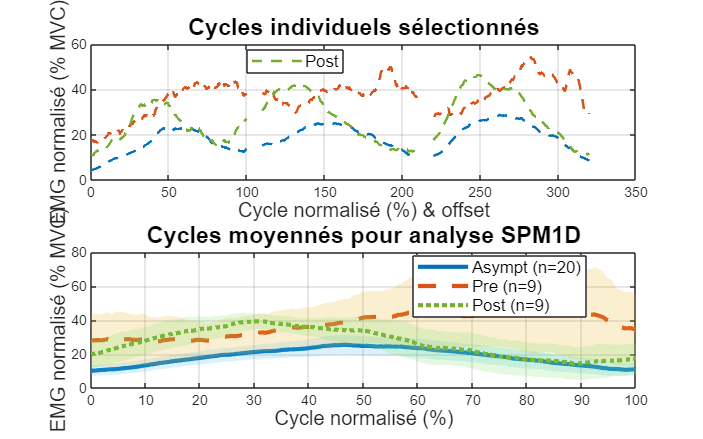

Alignement des courbes par DTW pour Asympt vs Pre...
Réalisation de l'analyse SPM1D pour Asympt vs Pre...
Type de test: Test t pour échantillons indépendants.


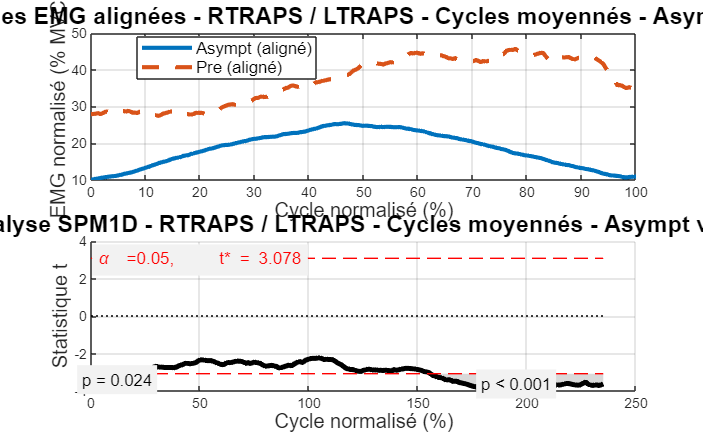

Alignement des courbes par DTW pour Asympt vs Post...
Réalisation de l'analyse SPM1D pour Asympt vs Post...
Type de test: Test t pour échantillons indépendants.


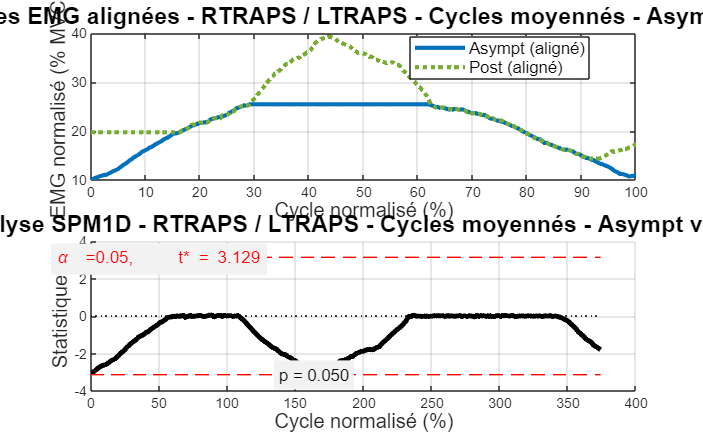

Alignement des courbes par DTW pour Pre vs Post...
Réalisation de l'analyse SPM1D pour Pre vs Post...
Type de test: Test t apparié (pour Pre vs Post).


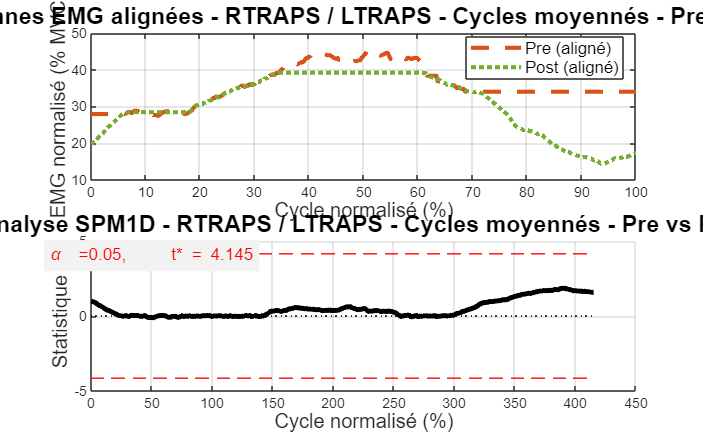


======== SÉLECTION DES CYCLES - MUSCLE: RSERRA / LSERRA ========
Veuillez sélectionner 3 cycles pour le muscle RSERRA / LSERRA.
Pour chaque cycle, cliquez sur le graphique pour marquer:
  - Le début du cycle (premier clic)
  - La fin du cycle (deuxième clic)

Sélection du CYCLE 1/3:
Cliquez pour marquer le DÉBUT du cycle 1...
Début du cycle 1: 0.02%
Cliquez pour marquer la FIN du cycle 1...
Fin du cycle 1: 0.35%
Sélection du CYCLE 2/3:
Cliquez pour marquer le DÉBUT du cycle 2...
Début du cycle 2: 0.37%
Cliquez pour marquer la FIN du cycle 2...
Fin du cycle 2: 0.62%
Sélection du CYCLE 3/3:
Cliquez pour marquer le DÉBUT du cycle 3...
Début du cycle 3: 0.67%
Cliquez pour marquer la FIN du cycle 3...
Fin du cycle 3: 0.95%

Tous les cycles ont été sélectionnés.
Création de la figure avec les cycles moyennés...



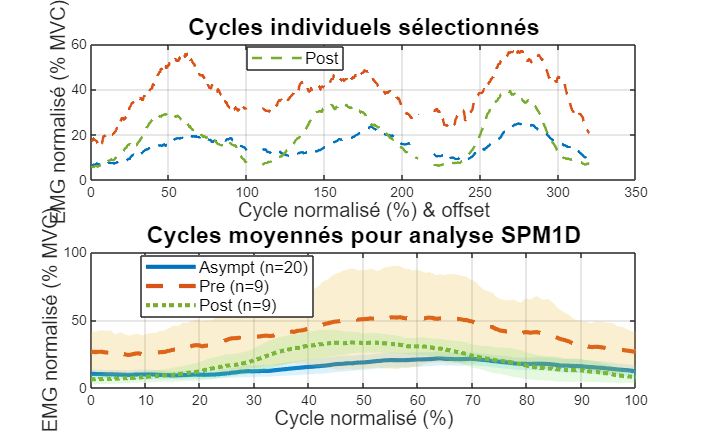

Alignement des courbes par DTW pour Asympt vs Pre...
Réalisation de l'analyse SPM1D pour Asympt vs Pre...
Type de test: Test t pour échantillons indépendants.


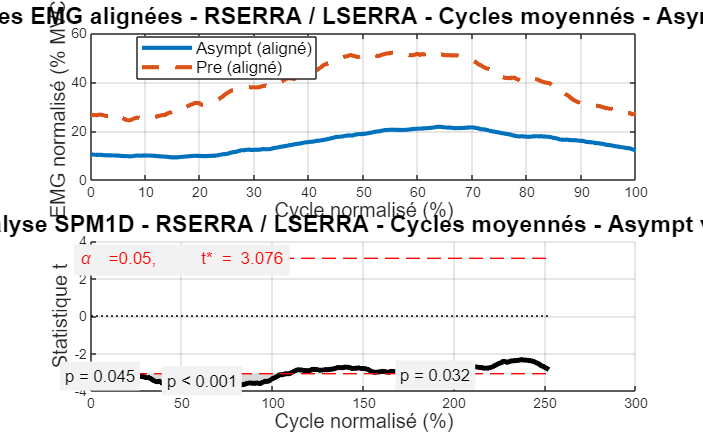

Alignement des courbes par DTW pour Asympt vs Post...
Réalisation de l'analyse SPM1D pour Asympt vs Post...
Type de test: Test t pour échantillons indépendants.


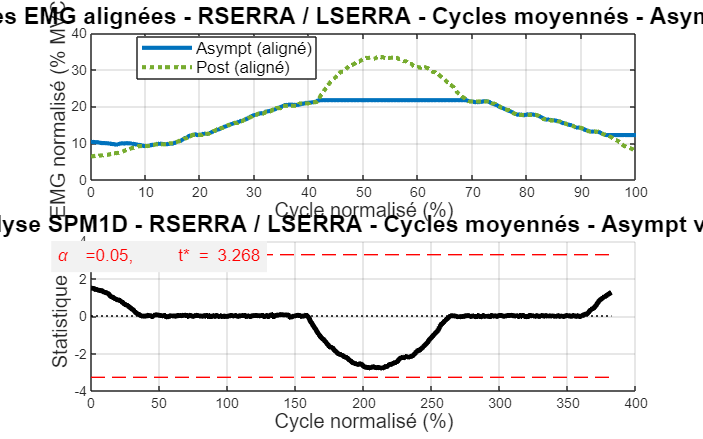

Alignement des courbes par DTW pour Pre vs Post...
Réalisation de l'analyse SPM1D pour Pre vs Post...
Type de test: Test t apparié (pour Pre vs Post).


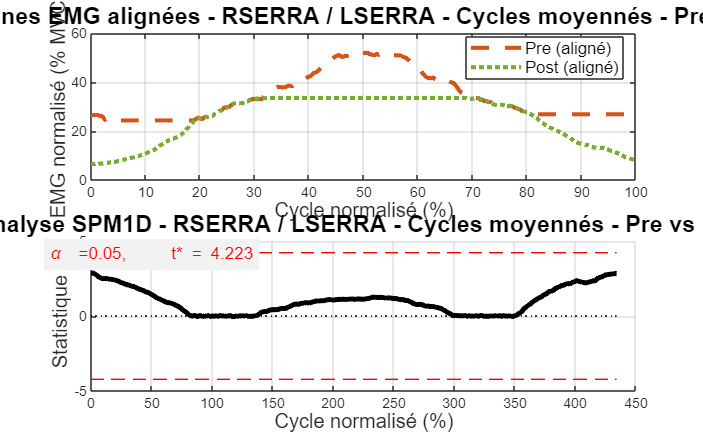


======== ANALYSE TERMINÉE ========
Tracé des profils EMG terminé pour 6 muscles.
Analyse avec moyenne de trois cycles terminée.
Pour chaque muscle, 3 cycles ont été sélectionnés et moyennés pour l'analyse SPM1D.
Les courbes ont été alignées temporellement avec DTW avant l'analyse.

Nombre de fichiers analysés: 3
  - Fichier 1: combined_functional_data_for_spm1d_asympt (Groupe: Asympt)
  - Fichier 2: combined_functional_data_for_spm1d_preOP (Groupe: Pre)
  - Fichier 3: combined_functional_data_for_spm1d_postOP (Groupe: Post)

Pour fermer toutes les figures: close all
Pour exporter les figures: utiliser la fonction saveas() ou exportgraphics()




% Exécuter la fonction principale avec SPM1D et DTW
plotCombinedEMGPerSubjectWithSPM1D(data_files, use_dtw);